%%%%%%%%%%%%%%%%%%%%%%
%%%bin the AQS data and plot
%%%created:11/03/22
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/AQS %change to data folder

fn = "etoAQS NATTS.xlsx";

%SDK
Tatl = readtable(fn, "Sheet", "atlanta", "VariableNamingRule", "preserve"); 
%other NATTS with Gen Coffee
Tother = readtable(fn, "Sheet", "not atlanta", "VariableNamingRule", "preserve");
sites = readtable("NATTS sites.xlsx", "sheet", "usedSites", "VariableNamingRule", "preserve");

Tall = [Tatl; Tother]; %append both together

cd ../..

%%%%%%%%%%%%%%%%%%%%%%
%%%bin the AQS data
%%%%%%%%%%%%%%%%%%%%%%

toPlot = struct; %structure to contain binned data
cities = unique(Tall.city); %grab all cities to bin
cities = [cities(1); cities]; %repeat atlanta to get both 149 and 150 methods

%%inputs
data = Tall;
minPoints = 4; %minimum number in bin
numStd = 3; %standard deviations away in which data will be excluded

for i = 1:length(cities)
    %%grab necessary pre-data
    city = cities(i); %current city
    cityInd = ismember(data.city, city);
    if strcmp(city, "Rubidoux")
        cityInd = ismember(data.city, "Robidoux"); % worko
    end
    Tcity = data(cityInd, :); %grab data for the city
    methodCode = Tcity.method_code(1); %grab method code
    %for atlanta specifically, match to method code
    if i == 1 %ATL 149
        methodCode = '149';
        cityInd = ismember(Tcity.method_code, methodCode);
        Tcity = Tcity(cityInd, :);
    elseif i == 2 %ATL 150
        methodCode = '150';
        cityInd = ismember(Tcity.method_code, methodCode);
        Tcity = Tcity(cityInd, :);
    end
    Tcity = sortrows(Tcity, "date_local"); %sort in chronological order

    %%create x values to iterate over, need 2 sets to avoid overlapping bin edges
    timeStart = dateshift(Tcity.date_local(1), "start", "month");
    timeEnd = dateshift(Tcity.date_local(end), "end", "month");
    midMonths1 = timeStart:calmonths(2):timeEnd; %midpoints, alternating months
    lowBin1 = (midMonths1 - calmonths(1))'; %lower bound on bin
    highBin1 = (midMonths1 + calmonths(1))'; %upper bound on bin
    midMonths2 = (timeStart+calmonths(1)):calmonths(2):timeEnd; %midpoints, alternating months
    lowBin2 = (midMonths2 - calmonths(1))'; %lower bound on bin
    highBin2 = (midMonths2 + calmonths(1))'; %upper bound on bin

    %%use BinAvg to calculate moving bins
    [outMean1, outStd1, outN1, outX1] = BinAvg(datenum(Tcity.date_local), Tcity.sample_measurement, ...
        datenum([lowBin1, highBin1]), minPoints, numStd, 0, 0);
    [outMean2, outStd2, outN2, outX2] = BinAvg(datenum(Tcity.date_local), Tcity.sample_measurement, ...
        datenum([lowBin2, highBin2]), minPoints, numStd, 0, 0);

    %%assemble timetable out
    time = [midMonths1'; midMonths2']; %assembles midpoints to plot
    avg = [outMean1; outMean2];
    stdev = [outStd1; outStd2];
    n = [outN1; outN2];
    TTout = timetable(time, avg, stdev, n); %put into time table
    TTout = sortrows(TTout); %sort in chronological order

    %put timetable into structure
    structString = strcat(city, "_", methodCode); %label for struct
    structString = erase(structString, " "); %remove whitespace for struct
    structString = erase(structString, "."); %remove period for struct
    toPlot.(structString) = TTout;

    %%grab total n for plotting
    nTot(i) = size(Tcity, 1);
end

toPlotNames = fieldnames(toPlot); %grab struct field names for easy plotting

%%%%%%%%%%%%%%%%%%%%%%
%%%plot
%%%%%%%%%%%%%%%%%%%%%%

%%get groups to plot
cityInd = ismember(Tall.method_code, '149'); 
group1 = unique(Tall.city(cityInd)); %passive 149
cityInd = ismember(Tall.method_code, '150'); 
group2 = unique(Tall.city(cityInd)); %pressurized 150
group3 = {'Providence', 'Roxbury', 'LA', 'Rubidoux', ...
    'Tampa', 'Pinellas County'}; %136, 172, 176

%%define colors
colors = distinguishable_colors(9);
colors(3, :) = [0.081, 0.84, 0.84]; %get rid of green
colors(6, :) = [0.8392, 0.6686, 0.4098]; %also get rid of yellow
colors(7, :) = sqrt(colors(7, :)); %lighten up green

%%define line types
lineTypes = {'-o', '-^', '-square', '-diamond', '-pentagram', ...
    '-.o', '-.^', '-.square', '-.diamond'};
markerSizes = [6, 6.6, 6.6, 6.6, 6.6, ...
    6, 6.6, 6.6, 6.6];

%%define limits and x ticks
xlims = datetime([2018, 2022], [7, 7], 1);
xtickss = (xlims(1)+calmonths(6)):calmonths(12):(xlims(2)-calmonths(6));

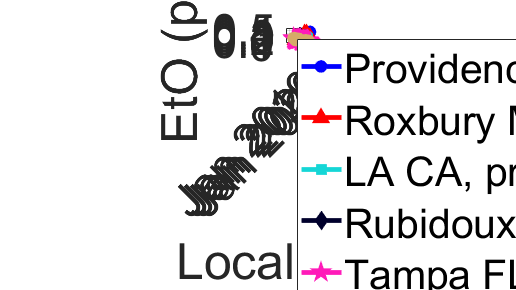

%%%VARIABLE INPUTS based on group
% %%group 1
% group = group1; %input for which group to plot
% plotATL149 = true; %for ATL, 149
% plotATL150 = false; %for ATL, 150
% addType = false; %for group 3
% ylims = [0, 2];
% ytickss = 0:0.5:2;
% fn = "Fig AQS 1.png";

% %%group 2
% group = group2; %input for which group to plot
% plotATL149 = false; %for ATL, 149
% plotATL150 = true; %for ATL, 150
% addType = false; %for group 3
% ylims = [-0.03, 1];
% ytickss = 0:0.2:1;
% fn = "Fig AQS 2.png";

%group 3
group = group3; %input for which group to plot
plotATL149 = false; %for ATL, 149
plotATL150 = false; %for ATL, 150
addType = true; %for group 3
legAddition = {'Entech 2000 (136)', 'Entech 2000 (136)', ...
    'pressurized (172)', 'pressurized (172)', ...
    'passive (176)', 'passive (176)'};
ylims = [-0.015, 0.5];
ytickss = 0:0.1:0.5;
fn = "Fig AQS 3.png";


%%%plot
fig = figure('Position', get(0, 'Screensize')); %for saving the figure
hold on
box on
grid on
pbaspect([1.6, 1, 1])
ax = gca;

hl = gobjects(length(group), 1); %for easier legend access
legStr = cell(length(group), 1); %for making legend

for i = 1:length(group)
    city = group{i}; %city name
    cityInd = find(ismember(cities, city));
    if strcmp(city, "Rubidoux")
        cityInd = find(ismember(cities, "Robidoux")); % workaround bc I can't spell
    end
    structString = toPlotNames{cityInd}; %grab struct field name
    if i == 1 && plotATL149 == true %overwrite if ATL 149
        structString = 'Atlanta_149';
    elseif i == 1 && plotATL150 == true %or ATL 150
        structString = 'Atlanta_150';
    end
    toPlotCurrent = toPlot.(structString); %grab data to plot

    %%plotting parameters
    times = datenum(toPlotCurrent.Properties.RowTimes);

    %%plot line
    [hl(i), ~] = boundedline(times, toPlotCurrent.avg, ...
        toPlotCurrent.stdev, ...
        lineTypes{i}, ...
        'nan', 'gap', 'alpha', 'transparency', 0.05, ...
        'color', colors(i, :));
    hl(i).MarkerSize = markerSizes(i); %change line aspects
    hl(i).MarkerFaceColor = colors(i, :);
    hl(i).LineWidth = 3.5;
    
    inds = ismember(sites.city, city); %find the state of the site
    legStr{i} = strcat(group{i}, " ", sites.state(inds), ...
        ", n=", num2str(nTot(cityInd(1)))); %legend string
    if addType == true %%for group 3
        legStr{i} = strcat(group{i}, " ", sites.state(inds), ...
        ", ", legAddition{i}, ...
        ", n=", num2str(nTot(cityInd(1)))); %legend string
    end
end

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "mmm yyyy");
ylim(ylims)
yticks(ytickss);

%%labels
ax.FontSize = 34;
xlabel("Local Time")
ylabel("EtO (ppb)")
legend(hl(:), legStr{:}, "location", "northwest")

hold off

% %%export the figure
% cd ../Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ../Data